### Setup of environment

clear variables
%% EXAMPLE: Multi-Robot Swarm Behavior
% Copyright 2018 The MathWorks, Inc.

%% Create a multi-robot environment
numRobots = 6;
env = MultiRobotEnv(numRobots);
env.robotRadius = 0.30;
env.showTrajectory = false;
env.hasObjects = false;
env.hasLidar = true;
env.showTrajectory = ones(1,numRobots);
env.robotColors = rand(6,3);
env.plotSensorLines = false; % So the sensor lines don't dominate the visuals

% Load a map as png and apply it to the environment
resolution = 30; % Smaller resolution corresponds to bigger map, and vice versa

image = imread('map/Custom_map.png');
grayimage = rgb2gray(image);
bwimage = grayimage < 0.5;

height = size(image, 1)/resolution;
width = size(image, 2)/resolution;

grid = binaryOccupancyMap(bwimage, resolution);
grid.GridLocationInWorld = [-width/2, -height/2];

env.mapName = "grid";

% Create robot detectors for all robots
lidars = cell(1,numRobots);
scanAngles = linspace(deg2rad(0),deg2rad(359),360);
for rIdx = 1:numRobots
    lidars{rIdx} = MultiRobotLidarSensor;
    lidars{rIdx}.robotIdx = rIdx;
    lidars{rIdx}.scanAngles = scanAngles;
    lidars{rIdx}.maxRange = 4;
end 

% Attach the defined lidar sensors to the robots
for rIdx = 1:numRobots
    attachLidarSensor(env, lidars{rIdx});
end

### Setup of constants

% Define time vector
stepTime = 2;
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:stepTime;  % Time array                

% Set the initial positions and orientations
radius = 1;
thetas = linspace((2*pi/6), 2*pi, numRobots);
poses = [radius*cos(thetas); radius*sin(thetas); thetas];

% Set the speed and velocity
speed = 0.2;
vels = speed*[cos(thetas); sin(thetas); zeros(1,numRobots)];

% Set constants used as thresholds for where the robot can go
stepDist = sqrt(vels(1,1)^2 + vels(2,1)^2) * (stepTime + sampleTime);
distThresh = 0.4;

% Define the FOV as a linspace used in each direction
numAngles = 41;  % Must be uneven to get an even amount below and above 0.
scanRange = linspace(-(numAngles-1)/2, (numAngles-1)/2, numAngles);

% Defining all constants we need in the the simulation loop
constants = struct( ...
    "Height", height, ...
    "Width", width, ...
    "NumRobots", numRobots, ...
    "DistancePerStep", stepDist, ...
    "DistanceTreshold", distThresh, ...
    "DistanceMin", 0.1, ...  % Treshold for how close we can be to a point before we say it has been visited
    "Speed", speed, ...
    "TimePerStep", stepTime, ...
    "SampleTime", sampleTime, ...
    "TimeVector", tVec, ...
    "ScanRange", scanRange ...
    )

constants = struct with fields:
              Height: 13.3333
               Width: 19.5000
           NumRobots: 6
     DistancePerStep: 0.4200
    DistanceTreshold: 0.4000
         DistanceMin: 0.1000
               Speed: 0.2000
         TimePerStep: 2
          SampleTime: 0.1000
          TimeVector: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000 2]
           ScanRange: [-20 -19 -18 -17 -16 -15 -14 -13 -12 -11 -10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]


## Simulation loop

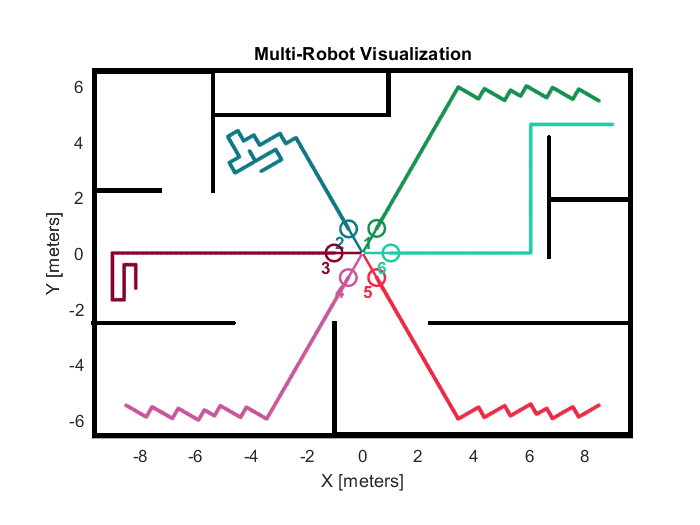

% Initialise arrays
ranges = cell(1, numRobots);
visitedPoints = zeros(1, numRobots, 2);

numPoints = 30;
for k = 1:2*numPoints
    % Update the environment
    updateEnvironment(env, poses, ranges, constants);
    
    for rIdx = constants.NumRobots:-1:1
        % Scan around the robot for objects
        scan = lidars{rIdx}();
        ranges{rIdx} = scan;
        
        % Remember the position the robot is currently in
        visitedPoints(k, rIdx, :) = poses(1:2, rIdx);
        
        % Explore for the number of points defined
        if k <= numPoints
            % Defining directions
            preDirecForward = getAngleBetween0and360(rad2deg(thetas(rIdx) - poses(3,rIdx)));
            preDirecLeft = getAngleBetween0and360(preDirecForward + 90);
            preDirecRight = getAngleBetween0and360(preDirecForward - 90);
            preDirecBackward = getAngleBetween0and360(preDirecForward + 180);
            
            % Determining the direction change, D, corresponding to the
            % exploration scheme
            if directionIsViable(preDirecForward, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), constants)
                D(rIdx) = 0;
                
            elseif directionIsViable(preDirecLeft, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), constants)
                D(rIdx) = pi/2;
                
            elseif directionIsViable(preDirecRight, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), constants)
                D(rIdx) = -pi/2;
                
            elseif directionIsViable(preDirecBackward, scan, poses(:, rIdx), visitedPoints(:, rIdx, :), constants)
                D(rIdx) = pi;
                
            else
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
            end
            
            % Find the distances to the robots with lower number than the
            % current robot
            distRobots = distanceToRobots(poses, rIdx);
            
            % We calculate the distance and angle difference to the closest robot
            [valClosestRobot, idxClosestRobot] = min(distRobots);
            angleDiff = abs(poses(3, rIdx) - poses(3, idxClosestRobot));
            
            % If another robot with higher priority is within collision distance,
            % we make the robot go back
            if valClosestRobot < stepDist*(1 - cos(angleDiff))
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
            end
            
            % Calculate the new orientation and linear velocity
            poses(3, rIdx) = thetas(rIdx) + D(rIdx);
            vels(:, rIdx) = speed*[cos(poses(3, rIdx)); sin(poses(3, rIdx)); 0];
        
        % Return to the beginning when we have explored for the number of
        % points defined
        else
            % Calculate the distance from the current point to the start
            distToStart = norm(poses(1:2, rIdx) - squeeze(visitedPoints(1, rIdx, :)));
            
            % If we are at the beginning, we stop
            if distToStart < constants.DistanceMin
                % Set the velocity to zero
                vels(:, rIdx) = [0; 0; 0];
            
            % Otherwise, we continue to follow the path back to the start
            else
                D(rIdx) = followPathBack(poses(1:2, rIdx), visitedPoints(:, rIdx, :), thetas(rIdx));
                
                % Calculate the new orientation and linear velocity
                poses(3, rIdx) = thetas(rIdx) + D(rIdx);
                vels(:, rIdx) = speed*[cos(poses(3, rIdx)); sin(poses(3, rIdx)); 0];
            end
        end
    end
    
    % Simulate the robots moving with the given direction and speed
    poses = simulateMoveRobots(env, poses, vels, ranges, constants);
    
    % Wait for x seconds
    pause(0.3)
end